clear;

%=======Задающий сигнал======
G_g = [0 2 0;
    -2 0 0;
    0 0 0];
Y_g = [1 0 -2];
w_g0 = [1; 0; 1];

%======Система==========

A = [5 8 5; -6 -9 -8; 6 6 5];
B = [2; 0; 0];
C = [2 -3 -2];
Bf = [-3 1; 3 0; 0 0];
D = [7];
Df = [5 6];
x0 = [0; 0; 0];
%=====Внешнее возмущение====
G_f = [0 1 0 1;
    -26 -7 20 -11;
    0 1 -1 2;
    16 4 -14 8];
Y_f = [2 0 -2 1;
    -4 -2 4 -3];
w_f0 = [1; 1; 1; 1];
wfx_0 = [1; 1; 1; 1; 0; 0; 0];

%====Синтез К========
K = [-6.5 -0.25 0.25];

%====Синтез Кg========
Kg = [0.0468 0.2563 -0.3738];

%====Синтез Кf========
Kf = [16.0012 6.4817 -11.3156 6.2353];


Q = [0.2000 -0.4000 -2.0000;    0.2500 -0.2500 -1.0000;    0.2400 -0.3200 -1.3333];
%iQ = pinv(Q)

Q1 = [0.2000 -0.4000 -2.0000 0;
    0.2500 -0.2500 -1.0000 0;
    0.2400 -0.3200 -1.3333 0; 0 0 0 0];
iQ = pinv(Q)

iQ =     2.4977   19.9963  -18.7441
   17.4930   39.9888  -56.2324
   -3.7488   -5.9981    9.3721


%=============================
Y = [1 1 1 1; 1 1 1 1]

Y =      1     1     1     1
     1     1     1     1


G = [-1 0 0 0; 0 -1.5 0 0; 0 0 -2 0; 0 0 0 -5]

G =    -1.0000         0         0         0
         0   -1.5000         0         0
         0         0   -2.0000         0
         0         0         0   -5.0000


C_b = [0 0.3333 0; 1.0000 1.0000 0];
%{
cvx_begin sdp

variable C_b(2, 3)

C_b*Bf == eye(2);
cvx_end
%}

cvx_begin sdp

variable Q_f(4, 4)

Q_f*G-G_f'*Q_f == Y_f'*Y;
cvx_end

Homogeneous problem detected; solution determined analytically.
Status: Solved
Optimal value (cvx_optval): +0
 



Q_f

Q_f =    10.4000    7.5200    5.4000    1.3050
    3.4000    2.6215    2.0000    0.6393
   -8.0000   -5.8215   -4.2000   -1.0504
    5.0000    3.6800    2.7000    0.7560


det(Q_f)

ans = 4.9361e-04


L = (-Y*pinv(Q_f))'

L =     9.2500    9.2500
    4.5000    4.5000
    6.6667    6.6667
  -11.8333  -11.8333


F = G_f-L*Y_f

F =    18.5000   19.5000  -18.5000   19.5000
  -17.0000    2.0000   11.0000   -2.0000
   13.3333   14.3333  -14.3333   15.3333
   -7.6667  -19.6667    9.6667  -15.6667


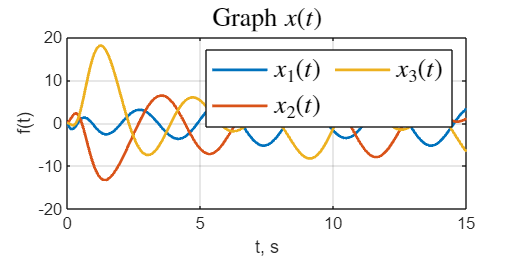


G = [-1 0 0; 0 -2 0; 0 0 -1.5];
Y = [1; 1; 1];

%=======Modeling=====
open_system('task_31_sim');
set_param('task_31_sim/x', 'VariableName', 'x')
set_param('task_31_sim/y', 'VariableName', 'y')
set_param('task_31_sim/u', 'VariableName', 'u')
set_param('task_31_sim/e', 'VariableName', 'e')
set_param('task_31_sim/ef', 'VariableName', 'ef')
set_param('task_31_sim/wf', 'VariableName', 'wf')
set_param('task_31_sim/wf_', 'VariableName', 'wf_')



out = sim('task_31_sim');
figure('Position', [100 100 800 400])

plot(out.x,'-', 'LineWidth',1.5);
%hold on
%plot(out.wf_,':', 'LineWidth',1.5);

grid()
title('Graph $x(t)$','Interpreter','latex',  'FontSize', 14)
legend('$x_{1}(t)$', '$x_{2}(t)$', '$x_{3}(t)$', 'Interpreter','latex',  'FontSize', 14, 'NumColumns', 2)
%legend('$w_{f1}(t)$', '$w_{f2}(t)$', '$w_{f3}(t)$', '$w_{f4}(t)$', ...
%    '$\hat{w}_{f1}(t)$', '$\hat{w}_{f2}(t)$', '$\hat{w}_{f3}(t)$','$\hat{w}_{f4}(t)$','Interpreter','latex',  'FontSize', 14, 'NumColumns', 2)
ylabel('f(t)')
xlabel('t, s')

%ylim([-35 30])
%hold off